# ENS - Homework 2

Creato da: Dandolo Giacomo (S296525) Favellato Francesco (S312697) Genduso Cristina (S293536)

clear all;
clc;

## Carica audio

[classic, fs_classic] = audioread('audio/the_wormhole.wav');
T_classic = 90;
[rock, fs_rock] = audioread('audio/crazy_train.wav');
T_rock = 296;

## Brano classico (C)

f_c = fs_classic;               % frequenza di campionamento
T_0 = 0.000442;                 % durata della porta (tempo)
n_bit = 20;
N = 2^n_bit;                    % numero di campioni
M = ceil(length(classic)/N);
n = -(N/2-1) : (N/2);
f = (n/N)*f_c/1000;             % frequenze per l'asse x del grafico

## C0 - Spettro di ingresso

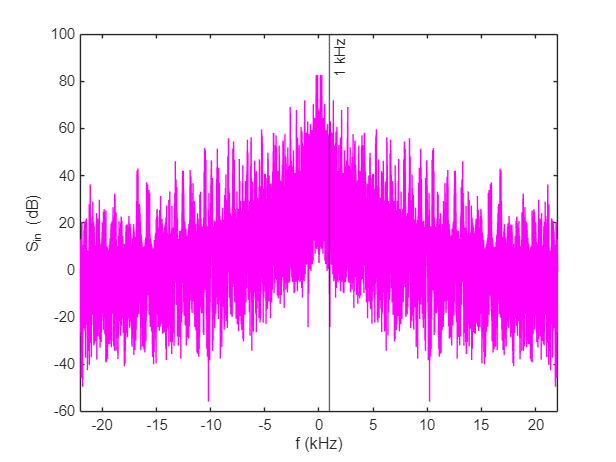

x = classic(1:M:length(classic));
y = fftshift(abs(fft(x, N)));

Sy = abs(y).^2;
Sy_dB = 10.*log10(Sy);

plot(f, Sy_dB, 'magenta');
xline(1, '-', '1 kHz');
xlabel('f (kHz)');
ylabel('S_{in} (dB)');
xlim([-f_c/2000, f_c/2000]);

## C1 - Funzione porta discreta nel tempo

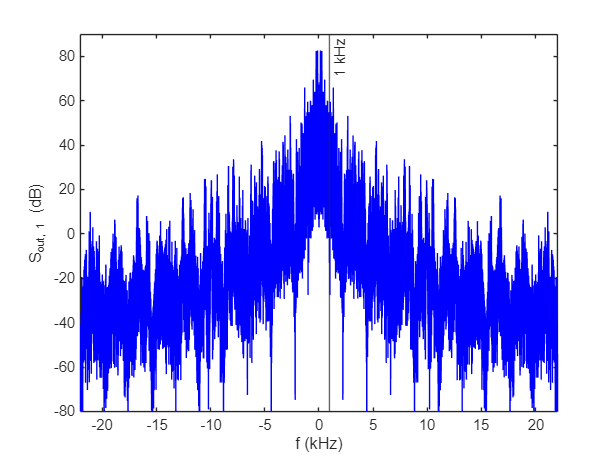

% Funzione porta nel dominio del tempo
n_uno = ceil(T_0 * f_c);                         % campioni = 1
n_zeri = N - n_uno;                              % campioni = 0
porta = [ ones(1, n_uno) zeros(1, n_zeri) ];     % funzione porta
porta = porta./sum(porta);                       % normalizzazione

% Spettro di uscita
y_porta = conv(x, porta);
Y_porta = fftshift(abs(fft(y_porta, N)));

Sy_porta = abs(Y_porta).^2;
Sy_porta_dB = 10.*log10(Sy_porta);

plot(f, Sy_porta_dB, 'blue');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('S_{out, 1} (dB)');
xlim([-f_c/2000, f_c/2000]);
ylim([-80 90]);

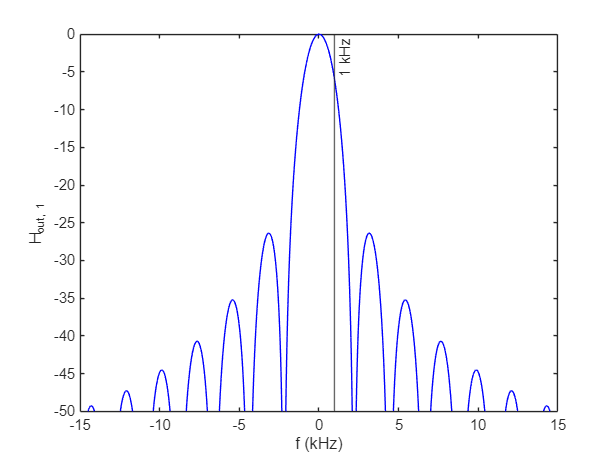

% Funzione di trasferimento
H_porta = 20.*log10(Sy_porta./Sy);

plot(f, H_porta, 'blue');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('H_{out, 1}');
ylim([-50 0]);

## C2 - Funzione porta in frequenza

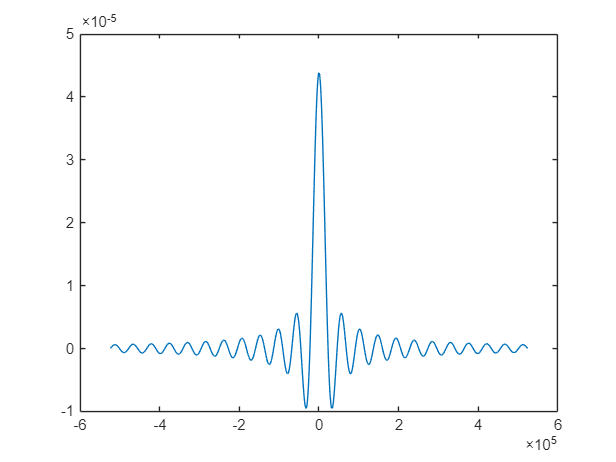

% Funzione sinc nel dominio del tempo
B = 1000;            
T = 1/(2*B);
func = @(t) (1/T)*sinc(t./T);
t = linspace(-N/2, N/2, 1024);
h_sinc = func(t);

plot(t, h_sinc);

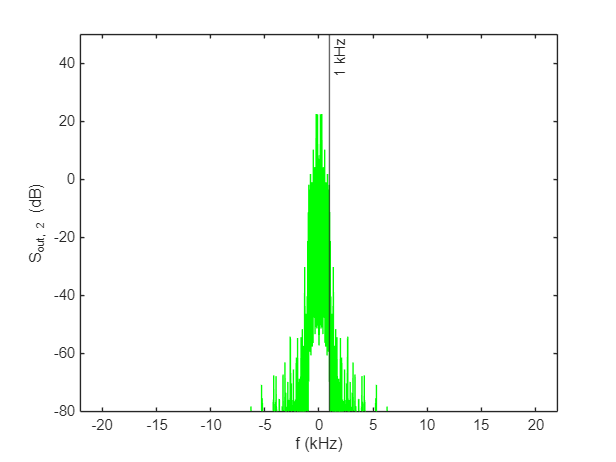

% Spettro di uscita
y_sinc = conv(x, h_sinc);
Y_sinc = fftshift(abs(fft(y_sinc, N)));

Sy_sinc = abs(Y_sinc).^2;
Sy_sinc_dB = 10.*log10(Sy_sinc);

plot(f, Sy_sinc_dB, 'green');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('S_{out, 2} (dB)');
xlim([-f_c/2000 f_c/2000]);
ylim([-80 50]);

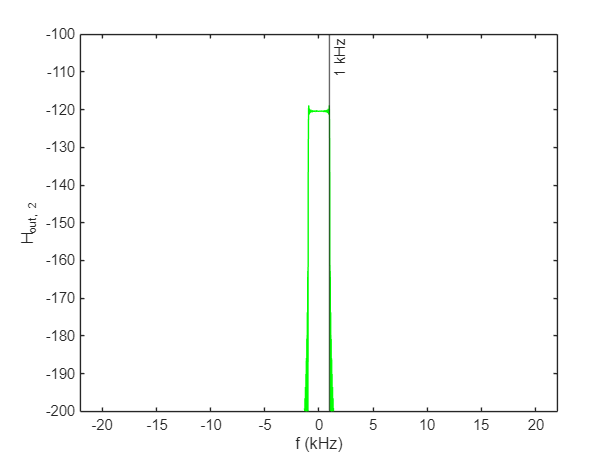

% Funzione di trasferimento
H_sinc = 20.*log10(Sy_sinc./Sy);
plot(f, H_sinc, 'green');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('H_{out, 2}');
xlim([-f_c/2000 f_c/2000]);
ylim([-200 -100]);

## C3 - Filtro passa-alto

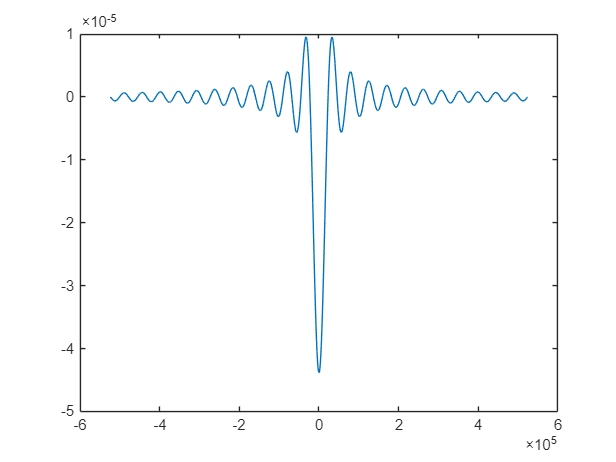

% Funzione di trasferimento 1-H(f) nel dominio del tempo
h_inv = dirac(t) - h_sinc;

plot(t, h_inv);

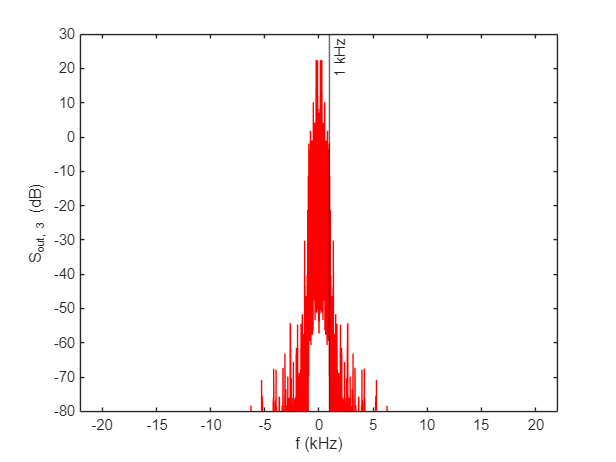

% Spettro di uscita
X = fft(x, N);
H_inv = fft(h_inv, N);
Y_inv = fftshift(X.*H_inv);

Sy_inv = abs(Y_inv).^2;
Sy_inv_dB = 10.*log10(Sy_inv);

plot(f, Sy_inv_dB, 'red');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('S_{out, 3} (dB)');
xlim([-f_c/2000, f_c/2000]);
ylim([-80 30]);

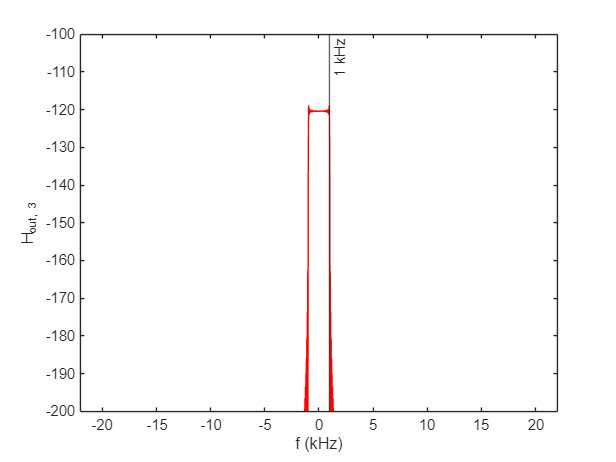

% Funzione di trasferimento
H_inv = 20.*log10(Sy_inv./Sy);
plot(f, H_inv, 'red');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('H_{out, 3}');
xlim([-f_c/2000 f_c/2000]);
ylim([-200 -100]);

## C4 - Ascolto

% Originale
sound(classic, f_c);
pause;
clear sound;

% Funzione porta discreta nel tempo
sound(Y_porta, f_c);
pause;
clear sound;

% Funzione porta in frequenza
sound(Y_sinc, f_c);
pause;
clear sound;

% Filtro passa-alto
%sound(Y_inv, f_c);
pause;
clear sound;

## Brano rock (R)

f_c = fs_rock;                  % frequenza di campionamento
T_0 = 0.000442;                 % durata della porta (tempo)
n_bit = 20;
N = 2^n_bit;                    % numero di campioni
M = ceil(length(rock)/N);
n = -(N/2-1) : (N/2);
f = (n/N)*f_c/1000;             % frequenze per l'asse x del grafico

## R0 - Spettro di ingresso

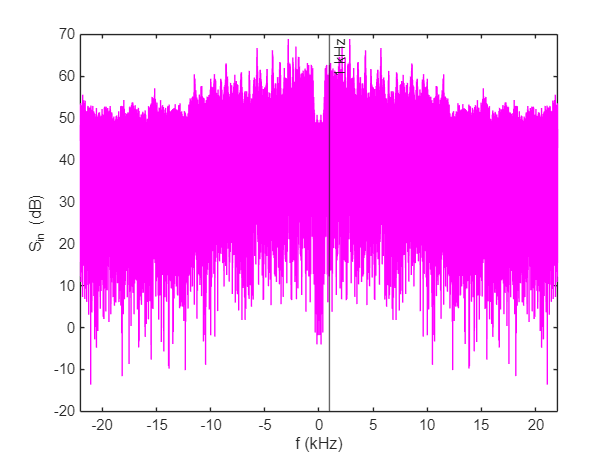

x = rock(1:M:length(rock));
y = fftshift(abs(fft(x, N)));

Sy = abs(y).^2;
Sy_dB = 10.*log10(Sy);

plot(f, Sy_dB, 'magenta');
xline(1, '-', '1 kHz');
xlabel('f (kHz)');
ylabel('S_{in} (dB)');
xlim([-f_c/2000, f_c/2000]);

## R1 - Funzione porta discreta nel tempo

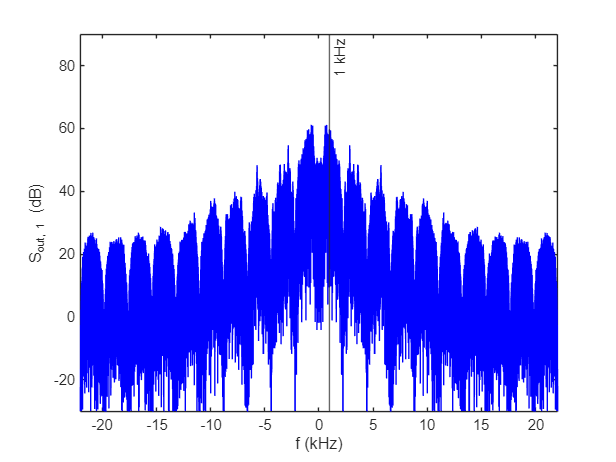

% Funzione porta nel dominio del tempo
n_uno = ceil(T_0 * f_c);                         % campioni = 1
n_zeri = N - n_uno;                              % campioni = 0
porta = [ ones(1, n_uno) zeros(1, n_zeri) ];     % funzione porta
porta = porta./sum(porta);                       % normalizzazione

% Spettro di uscita
y_porta = conv(x, porta);
Y_porta = fftshift(abs(fft(y_porta, N)));

Sy_porta = abs(Y_porta).^2;
Sy_porta_dB = 10.*log10(Sy_porta);

plot(f, Sy_porta_dB, 'blue');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('S_{out, 1} (dB)');
xlim([-f_c/2000, f_c/2000]);
ylim([-30 90]);

% Funzione di trasferimento
H_porta = 20.*log10(Sy_porta./Sy);

plot(f, H_porta, 'blue');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('H_{out, 1}');
ylim([-50 0]);

## R2 - Funzione porta in frequenza

% Funzione sinc nel dominio del tempo
B = 1000;            
T = 1/(2*B);
func = @(t) (1/T)*sinc(t./T);
t = linspace(-N/2, N/2, 1024);
h_sinc = func(t);

plot(t, h_sinc);

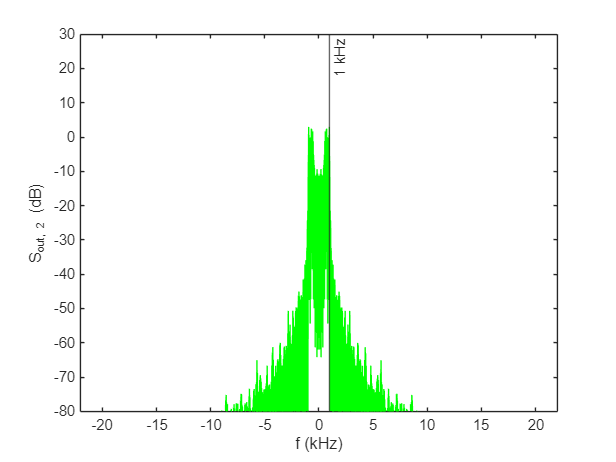

% Spettro di uscita
y_sinc = conv(x, h_sinc);
Y_sinc = fftshift(abs(fft(y_sinc, N)));

Sy_sinc = abs(Y_sinc).^2;
Sy_sinc_dB = 10.*log10(Sy_sinc);

plot(f, Sy_sinc_dB, 'green');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('S_{out, 2} (dB)');
xlim([-f_c/2000, f_c/2000]);
ylim([-80 30]);

% Funzione di trasferimento
H_sinc = 20.*log10(Sy_sinc./Sy);
plot(f, H_sinc, 'green');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('H_{out, 2}');
xlim([-f_c/2000 f_c/2000]);
ylim([-200 -100]);

## R3 - Filtro passa-alto

% Funzione di trasferimento 1-H(f) nel dominio del tempo
h_inv = dirac(t) - h_sinc;

plot(t, h_inv);

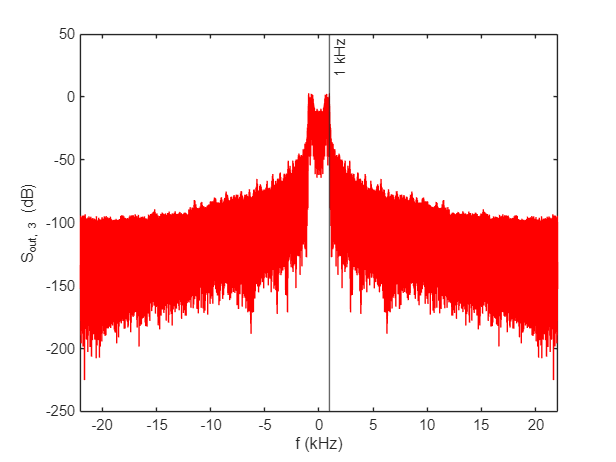

% Spettro di uscita
X = fft(x, N);
H_inv = fft(h_inv, N);
Y_inv = fftshift(X.*H_inv);

Sy_inv = abs(Y_inv).^2;
Sy_inv_dB = 10.*log10(Sy_inv);

plot(f, Sy_inv_dB, 'red');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('S_{out, 3} (dB)');
xlim([-f_c/2000 f_c/2000]);

## R4 - Ascolto

% Originale
sound(rock, f_c);
pause;
clear sound;

% Funzione porta discreta nel tempo
sound(Y_porta, f_c);
pause;
clear sound;

% Funzione porta in frequenza
sound(Y_sinc, f_c);
pause;
clear sound;

% Filtro passa-alto
%sound(Y_inv, f_c);

Error using sound (line 36)
Audio data must be real and floating point.

pause;
clear sound;